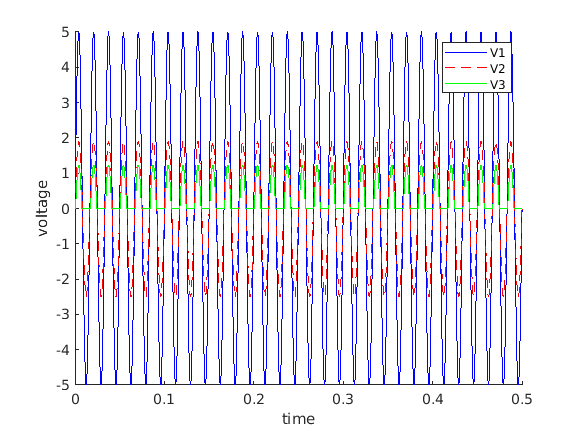

G = [1/50,-1/50,0,1;-1/50,(1/50+1/50),0,0;0,0,1/50,0;1,0,0,0];
C = [0,0,0,0;0,0,0,0;0,0,1e-6,0;0,0,0,0];
Amp = 5;
w = 2*pi*60;
tol = 1e-5;


tStart = 0;
tStop = 0.5;
dT = 1e-4;

T = tStart:dT:tStop;

Xn_1 = zeros(4,1);
Xstore = zeros(4,length(T));
Xstore(:,1) = Xn_1;


for n = 2:length(T)
    tn = T(n);
    B = [0;0;0;Amp*sin(w*tn)];
    
    %get the dF(Xn)/dXn
    dF = evaluateJacobian(Xn_1,G,C,dT);
    F = evaluateEquations(Xn_1,G,C,dT,B);
    Xn = Xn_1 - dF\F;
    
    while or(norm(evaluateEquations(Xn,G,C,dT,B),2)>=tol,norm(Xn-Xn_1,2)>=tol)
        Xn_1 = Xn;
        dF = evaluateJacobian(Xn_1,G,C,dT);
        F = evaluateEquations(Xn_1,G,C,dT,B);
        Xn = Xn_1 - dF\F;
        
    end
    Xn_1 = Xn;
    Xstore(:,n) = Xn_1;
end

figure(1)
hold on
plot(T,Xstore(1,:),"b")
plot(T,Xstore(2,:),"r--")
plot(T,Xstore(3,:),"g-")
legend("V1","V2","V3")
ylabel("voltage")
xlabel("time")

function J  = evaluateJacobian(X,G,C,dT)
% x is the input vector : it stores the valeus for the variables x1, x2, and x3. 
%  x1 = x(1), x2 = x(2) and x3 = x(3)
% J is the output Jacobian matrix of size 3x3
    Is = 1e-13;
    Vt = 0.025;
    J1 = G;
    J2 = C/dT;
    J3 = [0,0,0,0;
        0,exp((X(2)-X(3))/Vt)*Is/Vt,-exp((X(2)-X(3))/Vt)*Is/Vt,0;
        0,-exp((X(2)-X(3))/Vt)*Is/Vt,exp((X(2)-X(3))/Vt)*Is/Vt,0;
        0,0,0,0];
    J = J1+J2+J3;
end
function f  = evaluateEquations(X,G,C,dT,B)
    Is = 1e-13;
    Vt = 0.025;
    D = [0;Is*(exp((X(2)-X(3))/Vt)-1);-Is*(exp((X(2)-X(3))/Vt)-1);0];
    f = (G+C/dT)*X+D-B-(C/dT)*X;
end
